# **Résultats simulation Monte-Carlo intercalibrage**

## **Données d'intercalibrage**

- **Instrument de référence**

disp(['uvp5-sn203'])

uvp5-sn203


- **Instrument à ajuster**

disp(['uvp5-sn002'])

uvp5-sn002


- **Cast de référence**

disp(['n°1'])

n°1


- **Rapport d'intercalibrage correspondant **

disp(['uvp_calibration_report_of_uvp5sn002_from_uvp5sn203_20171202_rep_20200324.pdf'])

uvp_calibration_report_of_uvp5sn002_from_uvp5sn203_20171202_rep_20200324.pdf


## **Résultats Aa**

q_alpha = 1.96;

% Analyse statistique Aa
moy_Aa = mean(aa_adj);
med_Aa = median(aa_adj);
s_Aa = std(aa_adj);
[f, xi] = ksdensity(aa_adj);% estimation de la densité de probabilité à partir des fonctions de kernel

I_Aa = [moy_Aa - q_alpha * s_Aa ; moy_Aa + q_alpha * s_Aa ] ; 
I_Aa_bis = [quantile(aa_adj, 0.025) ; quantile(aa_adj, 0.975)];


 
disp(['------------------------ Résultats Monte-Carlo ------------------------'])

------------------------ Résultats Monte-Carlo ------------------------


disp(['Valeur moyenne                   : ', num2str(moy_Aa)])

Valeur moyenne                   : 0.011548


disp(['Intervalle de confiance à 95%    : [', num2str(I_Aa(1)) ,' ; ',num2str(I_Aa(2)) ']'])

Intervalle de confiance à 95%    : [0.0029135 ; 0.020183]


disp(['Valeur médiane                   : ', num2str(med_Aa)])

Valeur médiane                   : 0.011052


disp(['Intervalle interquantile à 95%   : [', num2str(I_Aa_bis(1)) ,' ; ',num2str(I_Aa_bis(2)) ']'])

Intervalle interquantile à 95%   : [0.0045077 ; 0.021489]


disp(['------------------------ Résultat intercalibrage ------------------------'])

------------------------ Résultat intercalibrage ------------------------


disp(['Valeur Aa_adj intercalibrage      : ', num2str(0.010262)])

Valeur Aa_adj intercalibrage      : 0.010262


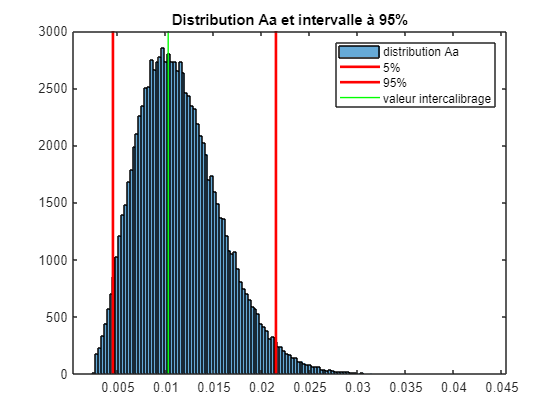


% histogramme de fréquence pour Aa 
figure(1);
histogram(aa_adj);
title('Distribution Aa et intervalle à 95%')
hold on;
line([I_Aa_bis(1), I_Aa_bis(1)], ylim, 'LineWidth', 2, 'Color', 'r');
line([I_Aa_bis(2), I_Aa_bis(2)], ylim, 'LineWidth', 2, 'Color', 'r');
line([0.010262, 0.010262], ylim, 'LineWidth', 1, 'Color', 'g') % valeur de Aa du rapport d'intercalibrage
legend('distribution Aa', '5%','95%', 'valeur intercalibrage');
hold off;

## Résultats exp

% Analyse statistique expo
moy_expo = mean(expo_adj);
med_expo = median(expo_adj);
s_expo = std(expo_adj);

I_exp = [moy_expo - q_alpha * s_expo ; moy_expo + q_alpha * s_expo ] ; 
I_exp_bis = [quantile(expo_adj,0.025) ; quantile(expo_adj,0.975)] ;


disp(['------------------------ Résultats Monte-Carlo ------------------------'])

------------------------ Résultats Monte-Carlo ------------------------


disp(['Valeur moyenne                   : ', num2str(moy_expo)])

Valeur moyenne                   : 1.1678


disp(['Intervalle de confiance à 95%    : [', num2str(I_exp(1)) ,' ; ',num2str(I_exp(2)) ']'])

Intervalle de confiance à 95%    : [0.99728 ; 1.3382]


disp(['Valeur médiane                   : ', num2str(med_expo)])

Valeur médiane                   : 1.1659


disp(['Intervalle interquantile à 95%   : [', num2str(I_exp_bis(1)) ,' ; ',num2str(I_exp_bis(2)) ']'])

Intervalle interquantile à 95%   : [1.0597 ; 1.306]


disp(['------------------------ Résultat intercalibrage ------------------------'])

------------------------ Résultat intercalibrage ------------------------


disp(['Valeur exp_adj intercalibrage      : ', num2str(1.1785)])

Valeur exp_adj intercalibrage      : 1.1785


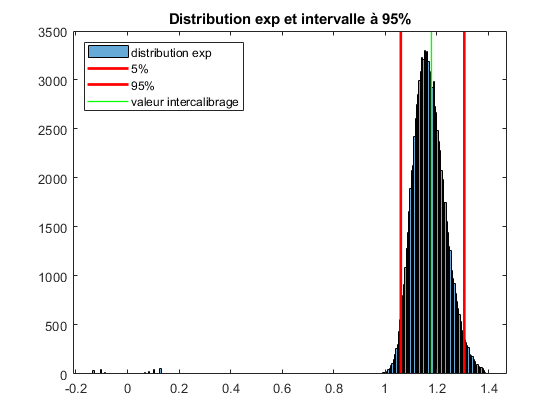


% histogramme de fréquence pour exp 
figure(2);
histogram(expo_adj);
title('Distribution exp et intervalle à 95%')
hold on;
line([I_exp_bis(1), I_exp_bis(1)], ylim, 'LineWidth', 2, 'Color', 'r');
line([I_exp_bis(2), I_exp_bis(2)], ylim, 'LineWidth', 2, 'Color', 'r');
line([1.1785, 1.1785], ylim, 'LineWidth', 1, 'Color', 'g'); % valeur de exp du rapport d'intercalibrage
legend('distribution exp', '5%','95%','valeur intercalibrage','Location','northwest')

## Résultats score


% Analyse statistique score
moy_score = mean(score);
med_score = median(score);
s_score = std(score);

I_score = [moy_score - q_alpha * s_score ; moy_score + q_alpha * s_score ] ; 
I_score_bis = [quantile(score,0.025) ; quantile(score,0.975)] ;

disp(['------------------------ Résultats Monte-Carlo ------------------------'])

------------------------ Résultats Monte-Carlo ------------------------


disp(['Valeur moyenne                  : ', num2str(moy_score)])

Valeur moyenne                  : 0.022647


disp(['Intervalle de confiance à 95%   : [', num2str(I_score(1)) ,' ; ',num2str(I_score(2)) ']'])

Intervalle de confiance à 95%   : [-0.077232 ; 0.12253]


disp(['Valeur médiane                  : ', num2str(med_score)])

Valeur médiane                  : 0.019966


disp(['Intervalle interquantile à 95%  : [', num2str(I_score_bis(1)) ,' ; ',num2str(I_score_bis(2)) ']'])

Intervalle interquantile à 95%  : [0.019966 ; 0.019966]


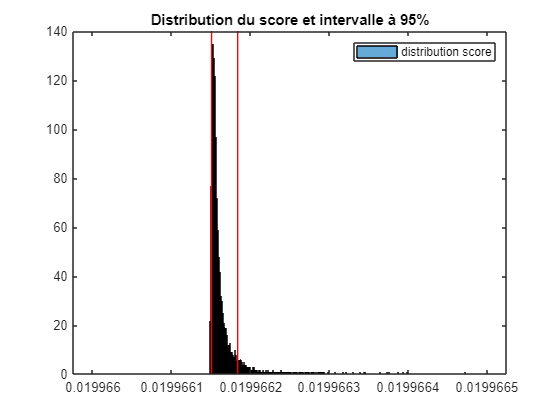

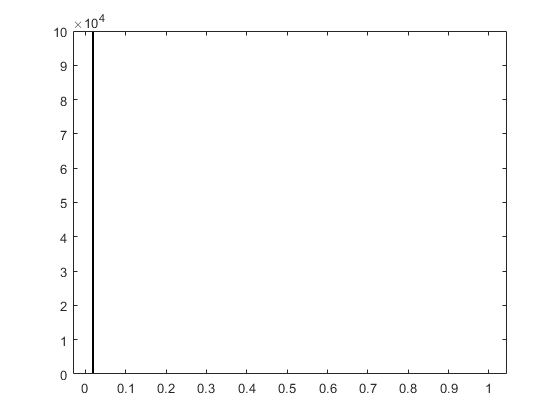

% histogramme des scores
figure(3);
edges = [0.019966:0.00000000001:0.0199665];
histogram(score,edges);
title('Distribution du score et intervalle à 95%')
hold on;
line([I_score_bis(1), I_score_bis(1)], ylim, 'LineWidth', 0.5, 'Color', 'r');
line([I_score_bis(2), I_score_bis(2)], ylim, 'LineWidth', 0.5, 'Color', 'r');
legend('distribution score')